### Exercises

#### Ex. 1.1

*For* loop

clear all

k = 8

k =      8


v = []


v =

     []



for i = 0:k 
    v = [v (2*i + 1)^2]
end

v =      1


v =      1     9


v =      1     9    25


v =      1     9    25    49


v =      1     9    25    49    81


v =      1     9    25    49    81   121


v =      1     9    25    49    81   121   169


v =      1     9    25    49    81   121   169   225


v =      1     9    25    49    81   121   169   225   289


*While *loop

i = 0

i =      0


while i < k
    v = [v (2*i + 1)^2]
    i = i + 1 
end

v =      1     9    25    49    81   121   169   225   289     1


i =      1


v =      1     9    25    49    81   121   169   225   289     1     9


i =      2


v =      1     9    25    49    81   121   169   225   289     1     9    25


i =      3


v =      1     9    25    49    81   121   169   225   289     1     9    25    49


i =      4


v =      1     9    25    49    81   121   169   225   289     1     9    25    49    81


i =      5


v =      1     9    25    49    81   121   169   225   289     1     9    25    49    81   121


i =      6


v =      1     9    25    49    81   121   169   225   289     1     9    25    49    81   121   169


i =      7


v =      1     9    25    49    81   121   169   225   289     1     9    25    49    81   121   169   225


i =      8


Vector syntax

v = [1:2:2*k+1].^2

v =      1     9    25    49    81   121   169   225   289


#### Ex. 1.2

Function definition

init_k(8); 

#### Ex. 1.3

k = 8

k =      8


M_k = diag(2.^(1./(1:2*k+1)))

M_k =      2.000000000000000e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0
                         0     1.414213562373095e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0
                         0                         0     1.259921049894873e+00                         0    

% Create last row
% lastRow = [1;1]*(1:2:2*k+1);
% lastRow = lastRow(:)'.^2;
M_k(end+1, 1:2:end) = init_k(k);
M_k(end, 2:2:end+1) = init_k(k);

% Create last col
M_k(2:2:end, end+1) = init_k(k);
% lastCol = [0;1]*(1:2:2*k+1);
% lastCol = lastCol(:)'.^2;
% lastCol(end) =[];

% Add last row and last col
% M_k(:, end + 1) = lastCol;
% M_k(end + 1, :) = lastRow;
display(M_k);

M_k =      2.000000000000000e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0
                         0     1.414213562373095e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0     1.000000000000000e+00
    

#### Ex. 1.4

Code A

x = 0;
while (x ~= 1)
    x = x + 1/16;
end

Code B (this is an infinite loop)

% x = 0;
% while (x ~= 1)
%     x = x + 0.1;
% end

#### Ex. 1.5

Find epsilon machine from scratch

x = 0;
e = 1e-20;
n = 1;
while (n+x == n)
    x = x + e;
end
display(2*x);

     2.220599999999850e-16



#### Ex. 1.6

realmax

ans =     1.797693134862316e+308


a = 1.0e+308;
b = -a;
c = 1.1e+308;
(a + b) + c

ans =     1.100000000000000e+308


(a + c) + b

ans =    Inf


#### Math function write

*linspace *command create a vector with a certain construction

help linspace;

 linspace Linearly spaced vector.
    linspace(X1, X2) generates a row vector of 100 linearly
    equally spaced points between X1 and X2.
 
    linspace(X1, X2, N) generates N points between X1 and X2.
    For N = 1, linspace returns X2.
 
    Class support for inputs X1,X2:
       float: double, single
 
    See also logspace, colon.

    Documentation for linspace
    Other functions named linspace



Let's write a function

f = @(x) sin(x);
x = linspace(0,2*pi,1000);

Let's now plot the function

figure();
plot(x, f(x), 'linewidth', 2);
hold on;

Now, let's define another function and plot it to the same figure

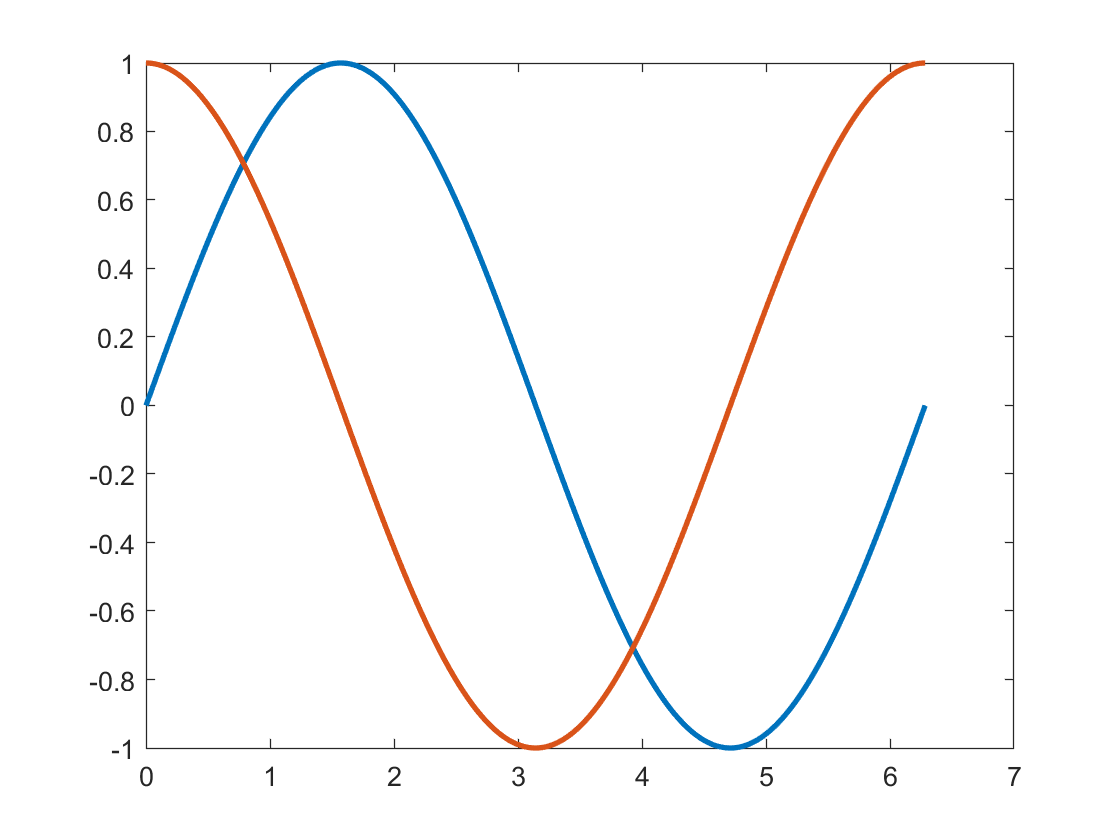

g = @(x) cos(x);
plot(x, g(x), 'linewidth', 2);
hold off;

We can put any information of a plot in a variable the the command

ax = gca()

ax =   Axes with properties:

             XLim: [0 7]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [1.300000000000000e-01 1.100000000000000e-01 7.750000000000000e-01 8.150000000000001e-01]
            Units: 'normalized'

  Show all properties


#### Ex. 1.7

format long e;

f = @(x) (exp(x) - 1) ./ x;
k = [1:20]';
x = 10.^(-k);
display([k x f(x)]);

     1.000000000000000e+00     1.000000000000000e-01     1.051709180756477e+00
     2.000000000000000e+00     1.000000000000000e-02     1.005016708416795e+00
     3.000000000000000e+00     1.000000000000000e-03     1.000500166708385e+00
     4.000000000000000e+00     1.000000000000000e-04     1.000050001667141e+00
     5.000000000000000e+00     9.999999999999999e-06     1.000005000006965e+00
     6.000000000000000e+00     1.000000000000000e-06     1.000000499962184e+00
     7.000000000000000e+00     1.000000000000000e-07     1.000000049433680e+00
     8.000000000000000e+00     1.000000000000000e-08     9.999999939225290e-01
     9.000000000000000e+00     1.000000000000000e-09     1.000000082740371e+00
     1.000000000000000e+01     1.000000000000000e-10     1.000000082740371e+00
     1.100000000000000e+01     1.000000000000000e-11     1.000000082740371e+00
     1.200000000000000e+01     1.000000000000000e-12     1.000088900582341e+00
     1.300000000000000e+01     1.000000000000000e-13

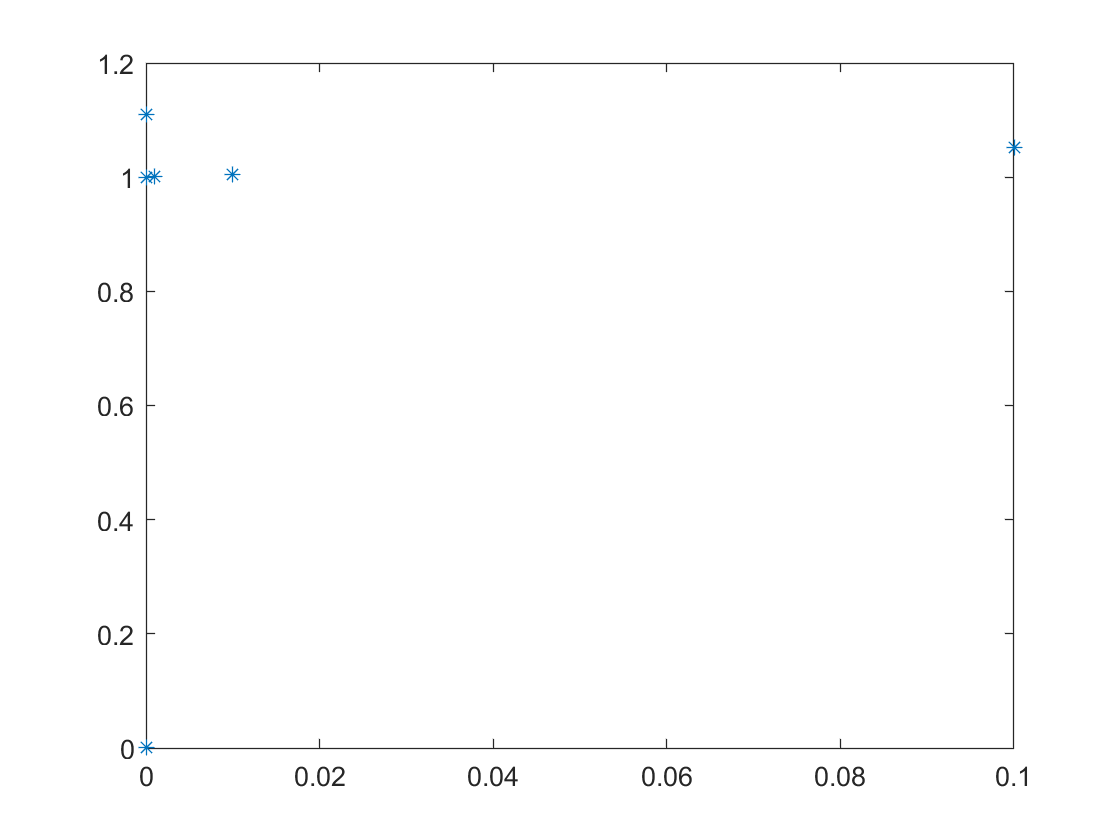

figure();
plot(x, f(x), '*');

As we can see we a lot of oscillations near to zero. One solution could be use Taylor expansions to get and approximation of *f(x) *around *x=0*. So let's define the Taylor expansion for the function *f(x).*

f_taylor_5 = @(x) 1 + 1/2*x + 1/6*x.^2 + 1/24*x.^3 + 1/120*x.^4;
display([k x f(x) f_taylor_5(x)]);

     1.000000000000000e+00     1.000000000000000e-01     1.051709180756477e+00     1.051709166666667e+00
     2.000000000000000e+00     1.000000000000000e-02     1.005016708416795e+00     1.005016708416667e+00
     3.000000000000000e+00     1.000000000000000e-03     1.000500166708385e+00     1.000500166708342e+00
     4.000000000000000e+00     1.000000000000000e-04     1.000050001667141e+00     1.000050001666708e+00
     5.000000000000000e+00     9.999999999999999e-06     1.000005000006965e+00     1.000005000016667e+00
     6.000000000000000e+00     1.000000000000000e-06     1.000000499962184e+00     1.000000500000167e+00
     7.000000000000000e+00     1.000000000000000e-07     1.000000049433680e+00     1.000000050000002e+00
     8.000000000000000e+00     1.000000000000000e-08     9.999999939225290e-01     1.000000005000000e+00
     9.000000000000000e+00     1.000000000000000e-09     1.000000082740371e+00     1.000000000500000e+00
     1.000000000000000e+01     1.000000000000000e-10   

### Function definition for exercises

function v = init_k (k)
   v = [1:2:2*k+1].^2;
end  